# Plot Results

clearvars
close all
set(0,'defaulttextInterpreter','latex') %latex axis labels
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
warning('off')

## Euclidean 3D

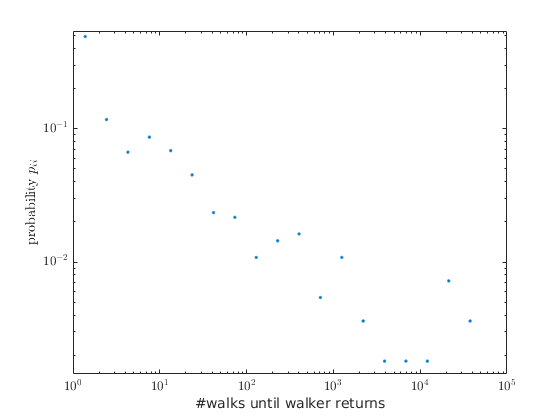

comebacktime3D=importfile("../../cmake-build-release/bin/euclidean3D_0.tsv");
for i=1:7
    imp=importfile("../../cmake-build-release/bin/euclidean3D_"+i+".tsv");
    cat(1,comebacktime3D,imp);
end

[counts3D,edges3D] = histcounts(comebacktime3D,logspace(0,log10(max(comebacktime3D)),20),'Normalization',"probability");
bin_middle3D=(edges3D(1:end-1)+edges3D(2:end))/2;
plot(bin_middle3D,counts3D,'.')
set(gca, 'xscale','log')
set(gca, 'yscale','log')
ylim([min(counts3D)*0.8,max(counts3D)*1.1])
xlabel("#walks until walker returns")
ylabel("probability $p_{ii}$")


bin_middle3D_log=log10(bin_middle3D)';
counts3D_log=log10(counts3D)';

ft = fittype( 'poly1' );
%excludedPoints = bin_middle3D_log < 4;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
%opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( bin_middle3D_log, counts3D_log, ft,opts );
dim=fitresult.p1*(-2)

dim = 0.9156

## Euclidean 2D

comebacktime2D=importfile("../../cmake-build-release/bin/euclidean2D_0.tsv");
for i=1:7
    imp=importfile("../../cmake-build-release/bin/euclidean2D_"+i+".tsv");
    cat(1,comebacktime2D,imp);
end

[counts2D,edges2D] = histcounts(comebacktime2D,logspace(0,log10(max(comebacktime2D)),20),'Normalization',"probability");
bin_middle2D=(edges2D(1:end-1)+edges2D(2:end))/2;
plot(bin_middle2D,counts2D,'.')
set(gca, 'xscale','log')
set(gca, 'yscale','log')
ylim([min(counts2D)*0.8,max(counts2D)*1.1])
xlabel("#walks until walker returns")
ylabel("probability $p_{ii}$")

bin_middle2D_log=log10(bin_middle2D)';
counts2D_log=log10(counts2D)';

ft = fittype( 'poly1' );
excludedPoints = bin_middle2D_log < 4;
opts = fitoptions( 'Method', 'LinearLeastSquares' );
opts.Exclude = excludedPoints;

% Fit model to data.
[fitresult, gof] = fit( bin_middle2D_log, counts2D_log, ft,opts );
dim=fitresult.p1*(-2)